# Improving Predictive Models

## 3. Reducing Predictors

### 3.1. Feature transformation

Use PCA to reduce the number of predictors in a Naive Bayes classifier.

load heartdisease
HD = heartdataNum.HeartDisease % Extract the response variable

HD = 427×1 categorical 배열
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 


numdata = heartdataNum{:,1:end-1} % Extract the numeric predictors as an array

numdata =     0.7083    0.3715    0.4865    0.6875    0.2532    0.4907    0.5833    0.6090    0.6795    0.6154    0.4107
    0.7917    0.5196    0.4324    0.6875    0.3038    0.6296    0.6667    0.2932    0.4872    0.6154    0.2679
    0.7917    0.3603    0.3784    0.5000    0.4810    0.2593    0.5000    0.4511    0.3590    0.5192    0.4643
    0.1667    0.4190    0.6216    0.9375    0.5570    0.3519    0.4667    0.8872    0.7115    0.4038    0.6250
    0.2500    0.2905    0.2973    0.4375    0.3924    0.3519    0.6000    0.7744    0.4872    0.4615    0.2500
    0.5625    0.3799    0.5297    0.8750    0.4177    0.2593    0.4167    0.8195    0.5192    0.4231    0.1429
    0.6875    0.4693    0.2432    0.3125    0.5443    0.4444    0.8333    0.6842    0.6154    0.5577    0.6429
    0.5833    0.7095    0.4054    0.5000    0.5570    0.2593    0.5000    0.7068    0.5192    0.5192    0.1071
    0.7083    0.4302    0.3514    0.4375    0.4430    0.3519    0.9167    0.5865    0.2308    0.4231  

vars = heartdataNum.Properties.VariableNames(1:end-1) % Extract the predictor names

vars = 1×11 cell 배열
    {'Age'}    {'Cholesterol'}    {'ExerciseDuration'}    {'METs'}    {'RestingHeartRate'}    {'RestingSystolic'}    {'RestingDiastolic'}    {'MaxHeartRate'}    {'PeakExSystolic'}    {'PeakExDiastolic'}    {'InducedSTDep'}


Perform PCA

[pcs,scrs,~,~,pexp]=pca(numdata)

pcs =    -0.2809   -0.0047   -0.2403    0.7545    0.3296   -0.2624    0.0065    0.3077   -0.0531   -0.0752   -0.1153
   -0.1041    0.1140    0.0894    0.2109   -0.0326    0.7831   -0.5252    0.1690    0.0609   -0.0054   -0.0352
    0.3924    0.1024   -0.2513   -0.1672   -0.0439   -0.1005   -0.2743    0.1784   -0.4887   -0.3635   -0.5044
    0.5872    0.0627   -0.3436    0.1060    0.2392    0.1758    0.1088    0.1315   -0.1826    0.1850    0.5806
    0.0096    0.2769    0.7302    0.0615    0.2929   -0.1578   -0.1199   -0.0197   -0.4794    0.0592    0.1657
   -0.2233    0.4989   -0.2497    0.0651    0.0705    0.1506    0.1520   -0.5771   -0.1139   -0.4634    0.1518
   -0.1251    0.4815   -0.0586   -0.0938   -0.0503    0.2415    0.5355    0.2770   -0.1464    0.4234   -0.3395
    0.4290    0.2876    0.2374    0.0261    0.3780   -0.0117    0.0992    0.0617    0.6352   -0.2456   -0.2360
    0.0269    0.4662   -0.2212    0.0005   -0.0967   -0.3662   -0.5254   -0.1919    0.1898    0.4904   -0.

scrs =     0.1105    0.1089   -0.4042    0.0212    0.2028   -0.0537   -0.0350    0.0884    0.0228   -0.0304    0.0844
   -0.0809    0.0750   -0.4009    0.1968    0.0474    0.1480    0.0543    0.0716   -0.2360   -0.0671    0.1720
   -0.0765   -0.2391   -0.0837    0.0736    0.2836   -0.0581    0.0226    0.1745   -0.1397   -0.0282    0.0543
    0.5920    0.1121   -0.1163   -0.4166    0.4789    0.0913   -0.2056   -0.0622   -0.0147    0.0728    0.1419
    0.2090   -0.0348    0.0836   -0.2165    0.0487    0.0313    0.1505   -0.1157    0.1748    0.0195   -0.0170
    0.5692   -0.0778   -0.1129    0.1249    0.2041    0.0019   -0.0195    0.0574    0.0248   -0.0277    0.1037
   -0.2675    0.2025   -0.0107   -0.0920    0.3983    0.0359    0.0390    0.1059    0.0748    0.1154   -0.0912
    0.1965    0.0043    0.1503    0.1882    0.0553    0.1812   -0.1817    0.1150    0.0350   -0.0200   -0.0048
   -0.0323   -0.0352    0.0026    0.1261    0.1574    0.1868    0.3468    0.1598   -0.1113    0.0358   -0

pexp =    31.7637
   17.5224
   11.1948
    9.9727
    7.6146
    5.7476
    5.2530
    3.6128
    3.4375
    1.9995


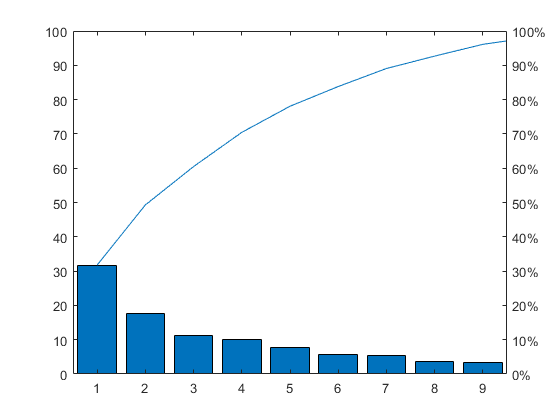

pareto(pexp)

 % You can find that the first eight principal components explain over 90% of variance

Fit a Naive Bayes Model on the reduced data

rng(1234)
prinComp8=scrs(:,1:8) % Use the first eight principal components

prinComp8 =     0.1105    0.1089   -0.4042    0.0212    0.2028   -0.0537   -0.0350    0.0884
   -0.0809    0.0750   -0.4009    0.1968    0.0474    0.1480    0.0543    0.0716
   -0.0765   -0.2391   -0.0837    0.0736    0.2836   -0.0581    0.0226    0.1745
    0.5920    0.1121   -0.1163   -0.4166    0.4789    0.0913   -0.2056   -0.0622
    0.2090   -0.0348    0.0836   -0.2165    0.0487    0.0313    0.1505   -0.1157
    0.5692   -0.0778   -0.1129    0.1249    0.2041    0.0019   -0.0195    0.0574
   -0.2675    0.2025   -0.0107   -0.0920    0.3983    0.0359    0.0390    0.1059
    0.1965    0.0043    0.1503    0.1882    0.0553    0.1812   -0.1817    0.1150
   -0.0323   -0.0352    0.0026    0.1261    0.1574    0.1868    0.3468    0.1598
   -0.2570    0.3158    0.0590   -0.2898    0.1685   -0.1400    0.1123    0.2013


part=cvpartition(HD,"KFold",10);

% Fit and evaluate the model on the full dataset.
mdlFull=fitcnb(numdata,HD,'DistributionNames','kernel',"CVPartition",part);
fullDataLoss=kfoldLoss(mdlFull)

fullDataLoss = 0.2740


% Fit and evaluate the model on the reduced dataset.
mdlReduced=fitcnb(prinComp8,HD,'DistributionNames','kernel',"CVPartition",part);
reduceDataLoss=kfoldLoss(mdlReduced)

reduceDataLoss = 0.2740

Visualize the relationship between the variables and the principal components

- biplot 

- heatmap (useful)

- parallelcoords 

- factor analysis

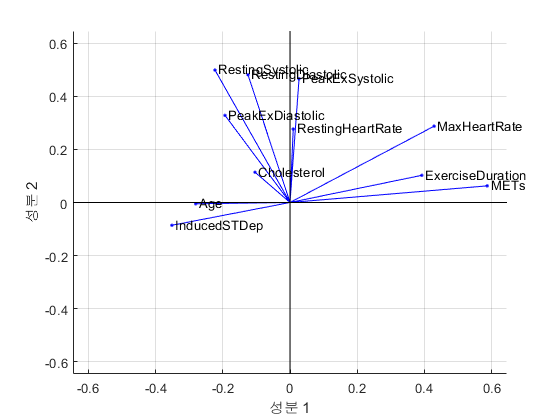

% Verify that the principal components are uncorrelated
%figure
%plotmatrix(scrs)

% 1.Visualize the relationship using biplot function
figure
biplot(pcs(:,1:2),'VarLabels',vars)

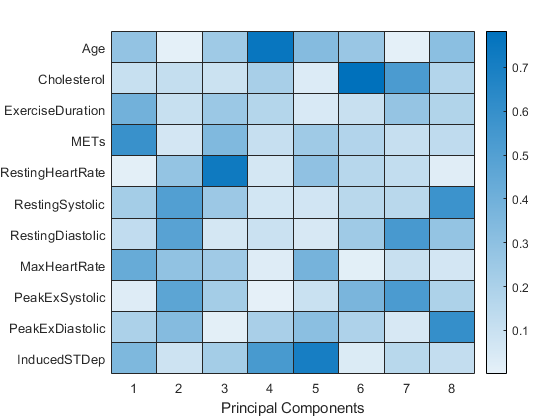


% 2.Visualize the relationship using heatmap function
figure
heatmap(abs(pcs(:,1:8)),'YDisplayLabels',vars)
xlabel('Principal Components')

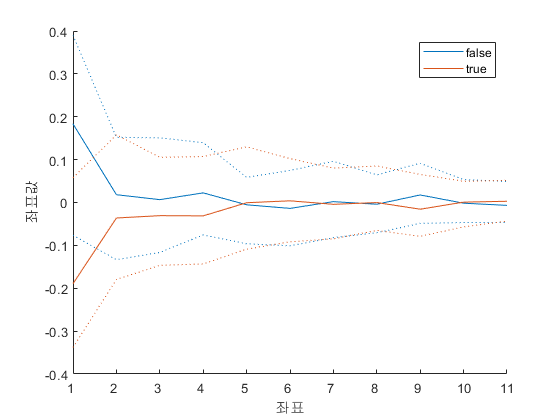

% 3. Visualize predictive power of the principal components
figure
parallelcoords(scrs,'Group',HD,"Quantile",0.25)

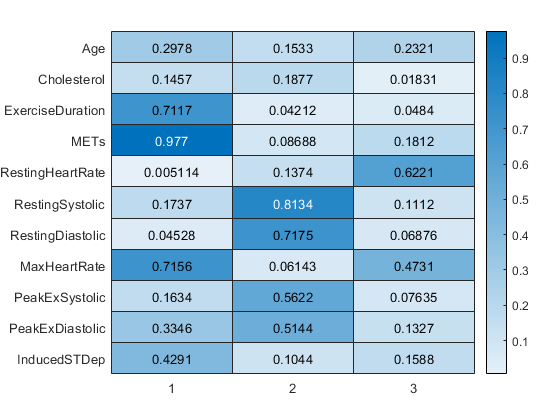



% 4. Factor Analysis
[Lambda,Psi,~,~,E]=factoran(numdata,3);
heatmap(abs(Lambda),'YDisplayLabels',vars)

### 3.2. Feature Selection

1. Built-in feature selection for decision tree models

open('treeselect.mlx')

**2. Sequential Feature Selection (IMPORTANT!)**

Perform sequential feature selection on the heart disease data for Naive Bayes and SVM classifiers.

rng(1234)
part = cvpartition(HD,'KFold',10);

Sequential feature selection on a Naive Bayes classifier.

rng(1234)
tokeep_nb=sequentialfs(@errorNB,numdata,HD,'cv',part);

ypred = 42×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 


error = 22

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 19

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     true 


error = 16

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     false 


error = 25

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 


error = 17

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 


error = 13

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 


error = 21

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 


error = 21

ypred = 42×1 categorical 배열
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 


error = 18

ypred = 42×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 18

ypred = 42×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 


error = 20

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 


error = 17

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 


error = 17

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 


error = 24

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 


error = 15

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     true 


error = 20

ypred = 43×1 categorical 배열
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 


error = 18

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 


error = 17

ypred = 42×1 categorical 배열
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     true 


error = 20

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     true 


error = 18

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 


error = 15

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 


error = 11

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 


error = 26

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 16

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 


error = 12

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 


error = 15

ypred = 43×1 categorical 배열
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     false 


error = 22

ypred = 42×1 categorical 배열
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 


error = 19

ypred = 42×1 categorical 배열
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 20

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 16

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 


error = 15

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 


error = 10

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 21

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 14

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 13

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 


error = 11

ypred = 43×1 categorical 배열
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     false 


error = 19

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 


error = 13

ypred = 42×1 categorical 배열
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 14

ypred = 42×1 categorical 배열
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 


error = 18

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 22

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 


error = 18

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 21

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 


error = 19

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 


error = 19

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 


error = 19

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 17

ypred = 42×1 categorical 배열
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 


error = 20

ypred = 42×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 


error = 18

ypred = 42×1 categorical 배열
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 


error = 19

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 


error = 23

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 


error = 18

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 


error = 21

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 


error = 19

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 


error = 17

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 


error = 17

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     true 


error = 21

ypred = 42×1 categorical 배열
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 17

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 22

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 14

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 19

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 


error = 16

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 21

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 16

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 


error = 19

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 


error = 17

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 


error = 15

ypred = 42×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 20

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 19

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     true 


error = 5

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 


error = 15

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 9

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 


error = 18

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 


error = 15

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 13

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 


error = 12

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     false 


error = 14

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 


error = 10

ypred = 42×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 13

ypred = 42×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 19

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 20

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 19

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 19

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 22

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 19

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 19

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 


error = 22

ypred = 42×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 19

ypred = 42×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 


error = 22

ypred = 42×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 17

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 


error = 24

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 


error = 15

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 21

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 17

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 


error = 17

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 18

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 18

ypred = 42×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 17

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 20

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 11

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 


error = 16

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 7

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 14

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 7

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 


error = 14

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 


error = 16

ypred = 42×1 categorical 배열
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 10

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 13

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 


error = 13

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 


error = 17

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 8

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 16

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 14

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 


error = 8

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 


error = 15

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 


error = 15

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 8

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 14

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 11

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 


error = 17

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 7

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 14

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 15

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 


error = 19

ypred = 43×1 categorical 배열
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 


error = 18

ypred = 42×1 categorical 배열
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 10

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 


error = 10

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     true 


error = 15

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 


error = 17

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 


error = 8

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 


error = 17

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 15

ypred = 43×1 categorical 배열
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 


error = 16

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 17

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 8

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 13

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 12

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 


error = 18

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 9

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 14

ypred = 43×1 categorical 배열
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 12

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 10

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 14

ypred = 43×1 categorical 배열
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 16

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 8

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 12

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     true 


error = 10

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     true 


error = 16

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 8

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 16

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 


error = 7

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 


error = 15

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 


error = 13

ypred = 42×1 categorical 배열
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 10

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 14

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 11

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 


error = 19

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 


error = 8

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 14

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     true 


error = 14

ypred = 43×1 categorical 배열
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 


error = 15

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 11

ypred = 42×1 categorical 배열
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 10

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 13

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 11

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 


error = 18

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 6

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 16

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 13

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 


error = 8

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 


error = 15

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 


error = 13

ypred = 42×1 categorical 배열
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 12

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 14

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 10

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 15

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 7

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 12

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 16

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 15

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 15

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 7

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 9

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     true 


error = 18

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 7

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 14

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 16

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 


error = 16

ypred = 43×1 categorical 배열
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 


error = 18

ypred = 42×1 categorical 배열
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 11

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 13

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 


error = 17

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 


error = 8

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 16

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 8

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 


error = 15

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 


error = 15

ypred = 42×1 categorical 배열
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 10

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 13

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 8

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 


error = 12

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 6

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 


error = 15

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 8

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 14

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 16

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 11

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 11

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 9

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 


error = 18

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 7

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 12

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 13

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 8

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 16

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 9

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 11

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 9

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 16

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 7

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 15

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 7

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 14

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 9

ypred = 42×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 13

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 11

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 7

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 14

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 16

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 10

ypred = 42×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 12

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 9

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 15

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 9

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 17

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 8

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 15

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 17

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 10

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 10

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 7

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 


error = 12

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 8

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 15

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 14

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 15

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 8

ypred = 42×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 14

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 7

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 16

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 8

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 14

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 16

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 10

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 15

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 10

ypred = 42×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 11

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 11

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 15

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 8

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 12

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 17

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 15

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 14

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 9

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 10

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 8

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 18

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 7

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 12

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 15

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 15

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 16

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 9

ypred = 42×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 12

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 9

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 


error = 14

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 8

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 14

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 


error = 14

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 8

ypred = 43×1 categorical 배열
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 


error = 17

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 16

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 11

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 12

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 8

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 16

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 7

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 15

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 


error = 15

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 7

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 


error = 14

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 14

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 11

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 12

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 9

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 12

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 7

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 15

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 15

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 14

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 15

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 12

ypred = 42×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 12

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 8

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 


error = 15

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 8

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 


error = 14

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 6

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 14

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 16

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 11

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 12

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 8

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 7

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 14

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 


error = 14

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 14

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 12

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 13

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 7

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 


error = 15

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 7

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 


error = 14

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 12

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 14

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 10

ypred = 42×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 14

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 9

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 6

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 14

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 17

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 7

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 14

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 16

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 12

ypred = 42×1 categorical 배열
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 12

ypred = 42×1 categorical 배열
     false 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     true 
     true 
     true 


error = 8

ypred = 43×1 categorical 배열
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     true 


error = 15

ypred = 43×1 categorical 배열
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     true 
     true 
     true 


error = 7

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     true 
     true 
     true 
     true 
     true 


error = 16

ypred = 43×1 categorical 배열
     false 
     true 
     true 
     true 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     true 


error = 9

ypred = 43×1 categorical 배열
     false 
     false 
     false 
     true 
     true 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     true 
     true 


error = 13

ypred = 43×1 categorical 배열
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     false 
     true 
     false 


error = 15

ypred = 42×1 categorical 배열
     true 
     false 
     false 
     true 
     false 
     false 
     true 
     false 
     false 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     false 
     true 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     true 
     false 
     true 
     false 
     true 


error = 12

ypred = 42×1 categorical 배열
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 
     false 
     false 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     false 
     false 
     false 
     true 
     false 
     true 
     false 
     true 
     true 
     true 
     true 
     true 


error = 14

vars(tokeep_nb)

ans = 1×3 cell 배열
    {'Age'}    {'MaxHeartRate'}    {'InducedSTDep'}


Compare the results with the full dataset.

% Naive Bayes with the full data set.
mdlFull=fitcnb(numdata,HD,'DistributionNames','kernel','CVPartition',part);

'numdata'은(는) 인식할 수 없는 함수 또는 변수입니다.

fullDataLoss=kfoldLoss(mdlFull)

% Naive Bayes with the selected predictors.
numdataSelectedNB=numdata(:,tokeep_nb)
mdlSelected=fitcnb(numdataSelectedNB,HD,'DistributionNames','kernel',"CVPartition",part)
selectedDataLoss=kfoldLoss(mdlSelected)

Sequential feature selection on a SVM classifier.

rng(1234)
tokeep_svm=sequentialfs(@errorSVM,numdata,HD,'cv',part);
vars(tokeep_svm)

ans = 1×2 cell 배열
    {'RestingDiastolic'}    {'MaxHeartRate'}


Compare the results with the full data set.

rng(1234)
% SVM with full data set.
ndlFull=fitcsvm(numdata,HD,'CVPartition',part);
fullDataLoss=kfoldLoss(ndlFull)

fullDataLoss = 0.2787


% SVM with the selected predictors.
numdataSelectedSVM=numdata(:,tokeep_svm);
mdlSelected=fitcsvm(numdataSelectedSVM,HD,'CVPartition',part);
selectedDataLoss=kfoldLoss(mdlSelected)

selectedDataLoss = 0.2740

Callback function: errorNB function returns the number of inaccurate predictions for `ytest` by a Naive Bayes classifier.

function error = errorNB(Xtrain,ytrain,xtest,ytest)
mdlnb = fitcnb(Xtrain,ytrain,'DistributionNames','kernel');
ypred=predict(mdlnb,xtest)
error= nnz(ypred ~= ytest)
end

Callback function: errorSVM function returns the number of inaccurate predictions for `ytest` by a SVM classifier.

function error = errorSVM(Xtrain,ytrain,Xtest,ytest)
mdlsvm = fitcsvm(Xtrain,ytrain);
ypred = predict(mdlsvm,Xtest);
error = nnz(ypred ~= ytest);
end